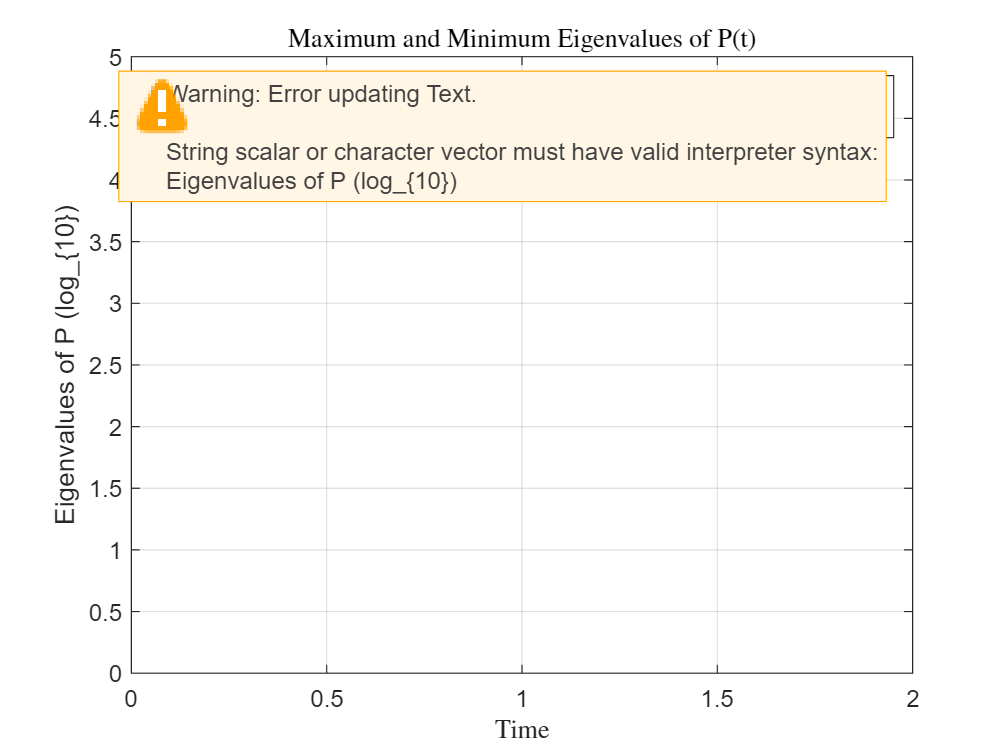


syms y t t2 n;
% Assume your variable is:
% local_results = { [1x180 struct] };
t0= 0;
N = 32;
kx = 0.22; 
kz = 0.67;
% k0= 0.1;

[x, D, D2, D4,w] =finitediff(N,2);
h=eye(size(D));
h1=eye(size(D));
k2=(kx.^2+b.^2)*h;
k=(kx.^2+b.^2).^0.5*h1;
w1=w.^0.5;
W=diag(w1);
d=D+k;
WW=W*d;
V=[WW,zeros(N-2,N-2);zeros(N-2,N-2),W]; %126*126
c=D2-k2;


%U
Cn=0;
NN=100;
k0 = 0.1;
Re= 500;
g=1-exp(-k0.*t); %Acc
g=exp(-k0.*t); %Dec
an = (pi*n).^2./Re;  %lately
m=diff(g,t);
a1=subs(m,t,0);
m2=diff(m,t);
a2=subs(m2,t,t2);
e=exp(an.*t2);
a3=simplify(e*a2);
a4=simplify(int(a3, t2, 0, t),'Steps',200);
a5=a4+a1;
aa=-2.*Re.*(-1).^n./(pi.*n).^3.*(a5)+Cn;
a6=simplify(aa.*exp(-an.*t).*sin(n.*y.*pi),'Steps',100);
b1=Re./6.*m.*(y.^3-y);
b2=g.*y;
bb=b1+b2;
a7 = 0;
for ii = 1:NN
    a7 = a7 + subs(a6, n, ii);
end
U=a7+bb;

mm=diff(U);
mm2=diff(mm);
% U_yi = (subs(U, y, yi(2:N)));
% m_yi = (subs(mm, y, yi(2:N)));
% m2_yi = (subs(mm2, y, yi(2:N)));

U_yi = (subs(U, y, x));
m_yi = (subs(mm, y, x));
m2_yi = (subs(mm2, y, x));
U_yi_function = matlabFunction(U_yi);
m_yi_function = matlabFunction(m_yi);


data = results{1};  % extract the struct array
n = numel(data);          % number of time steps

dt = 1;
T=200;
maxEig = zeros(1, n);
minEig = zeros(1, n);
t_steps = (T-t0)/dt;
eigvals = cell(t_steps, 1);
eigvecs = cell(t_steps, 1);

for i = 1:n
    P = data(i).P;               % extract P matrix
    eigVals = eig(P);            % compute eigenvalues (complex in general)
    eigReal = real(eigVals);     % take real part (if Hermitian, this equals eigenvalue)
    maxEig(i) = max(eigReal);
    minEig(i) = min(eigReal);
    [V_eig, D_eig] = eig(P);
    eigvals{i} = diag(D_eig);
    eigvecs{i} = V_eig;

end

% If you have a corresponding time vector, say data(i).t:
if isfield(data, 't')
    t_values = [data.t];
else
    t_values = 1:n;  % fallback to index
end

% Plot results
figure;
plot(t_values, log10(maxEig), 'LineWidth', 1.5); hold on;
plot(t_values, log10(minEig), 'LineWidth', 1.5);
xlabel('Time');
ylabel('Eigenvalues of P (log_{10})');
legend('Max eigenvalue', 'Min eigenvalue');
title('Maximum and Minimum Eigenvalues of P(t)');
grid on;

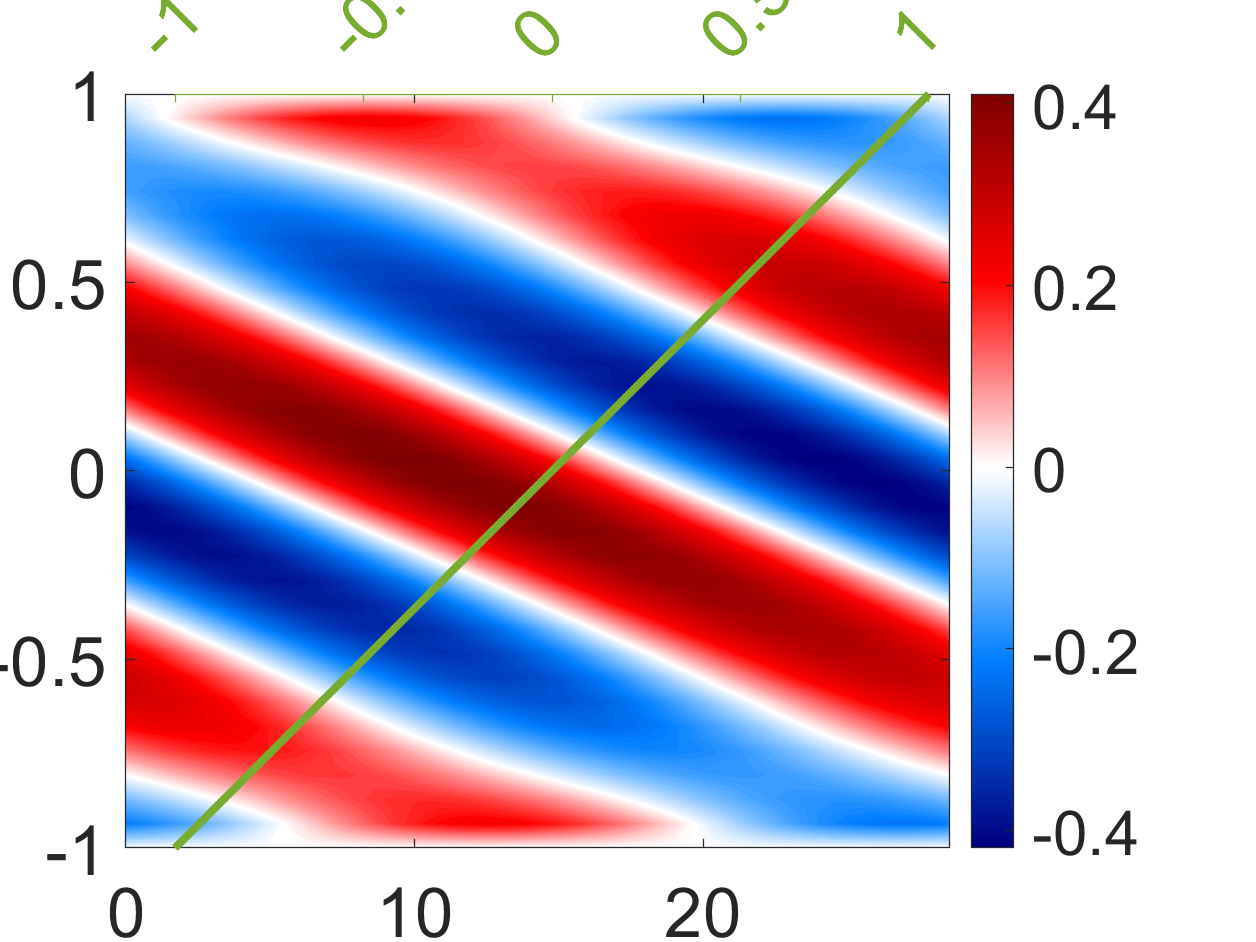




all_eigenvalues = eigvals;
all_eigenvectors = eigvecs;

Nx = 64;
        k2 = kx^2 + kz^2;
                
%        % After getting eigenvector q
%        for j1_ind = 1:length(t0)
%         max_eig(j1_ind) = max(all_eigenvalues(j1_ind,:));
%        end
        j1_max = 1;
         [~,max_idx] = max(all_eigenvalues{j1_max});
        t_current = t0 + (j1_max-1)*dt;

        
        
        q = all_eigenvectors{j1_max}(:,max_idx);

        q = inv(V)*q;
        
        % Split state vector
        v_interior = q(1:(N-2));
        wy_interior = q((N-2)+1:end);
        
        % Pad with boundary zeros (now size N)
        v_full = [0; v_interior; 0];
        wy_full = [0; wy_interior; 0];
        
        % Compute ∂v/∂y at INTERIOR points
        Dv_interior = D * v_interior;  % D: (N-2)x(N-2) matrix
        Dv_full = [0; Dv_interior; 0]; % Pad boundaries
        
        % Compute velocity components (now all size N)
        u_hat = (1/k2) * (1i*kx * Dv_full - 1i*kz * wy_full);
        v_hat = v_full;
        w_hat = (1/k2) * (1i*kz * Dv_full + 1i*kx * wy_full);
        
        y_grid = linspace(-1, 1, N)';
        x_grid = linspace(0, 2*pi/kx, Nx)'; % when kz = 0
%         x_grid = linspace(0, 2*pi/b, Nx)'; % when kx = 0, Z_grid
        [X, Y] = meshgrid(x_grid, y_grid);
        
        % kz = 0
        u_physical = real(u_hat .* exp(1i*kx*X));
        v_physical = real(v_hat .* exp(1i*kx*X));
        w_physical = imag(w_hat .* exp(1i*kx*X));

        %% kx = 0
%         u_physical = real(u_hat .* exp(1i*b*X));
%         v_physical = real(v_hat .* exp(1i*b*X));
%         w_physical = imag(w_hat .* exp(1i*b*X));

        max_abs = max(abs(u_physical(:)));
        g_current = exp(-k0 * t_current); % dec
%         g_current = 1- exp(-k0 * t_current); % Acc
        U_interior = U_yi_function(t_current);
        U_full   = [-g_current, U_interior, +g_current];  % size N×1

        dudy = m_yi_function(t_current);        
        P_2D = -(u_physical(2:end-1,:) .* v_physical(2:end-1,:)) .* dudy(:);
        P_norm = P_2D / max(abs(P_2D(:)));
        x_pos = pi/kx; % kz = 0
%         x_pos    = pi/b;     % kx = 0                               % center in x
        u_shift  = U_full + x_pos;                          % shifted x‐coordinate
        
        figure; clf;
        set(gcf,'Position',[100 100 800 600]);
        % 1) Primary axes for the contour:
        ax1 = axes('Position',[0.10 0.10 0.75 0.8]);
        contourf(ax1, X, Y, u_physical, 100, 'LineColor','none');
%         contourf(ax1, X(2:end-1,:), Y(2:end-1,:), P_norm, 100, 'LineColor','none');
        colormap(ax1, bluewhitered);
        colorbar(ax1,'Location','eastoutside');
%         caxis(ax1,[-1.5 1.5]);
        set(ax1,'FontSize',26,'Box','on');
        
        



        % 2) Overlay a second axes for U(y):
        ax2 = axes('Position',get(ax1,'Position'), ...
                   'XAxisLocation','top', ...
                   'YAxisLocation','right', ...
                   'Color','none', ...
                   'YTick',[], ...      % hide its y‑ticks
                   'Box','off', ...
                   'XColor','#77AC30', ...
                   'FontSize',26);
        set(ax2, 'YColor', 'none');      % hide that vertical line

        
        % 3) Link Y‑limits so the laminar curve sits at the correct vertical positions:
        linkprop([ax1 ax2],{'YLim'});
        ylim(ax2, ax1.YLim);
        
        % 4) Give ax2 its own X‑limits = [-1,1] (laminar velocity range):
        xlim(ax2, [-1 1]);
        
        % 5) Force equal data‑unit aspect on ax2:
        %    one “unit” in x (e.g. from -1 to 0) equals one “unit” in y
        daspect(ax2, [1 1 1]);
        
        % 6) Set evenly‑spaced ticks from -1 to +1:
        lam_ticks = linspace(-1,1,5);
        set(ax2, 'XTick', lam_ticks, 'XTickLabel', arrayfun(@num2str, lam_ticks,'Uni',0));
        % after creating ax2 …
        set(ax2, 'Units', 'centimeters');          % work in cm
        pos = get(ax2, 'Position');                % [left bottom width height]
        pos(1) = pos(1) - 0.75;                       % move left by 1 cm
        set(ax2, 'Position', pos, 'Units', 'normalized');  % apply and switch back
%         axis(ax2,'equal');            

        
        
        % 7) Plot the laminar profile on ax2:
        hold(ax2,'on');
        plot(ax2, U_full, y_grid, 'LineWidth',3, 'Color','#77AC30');
        hold(ax2,'off');

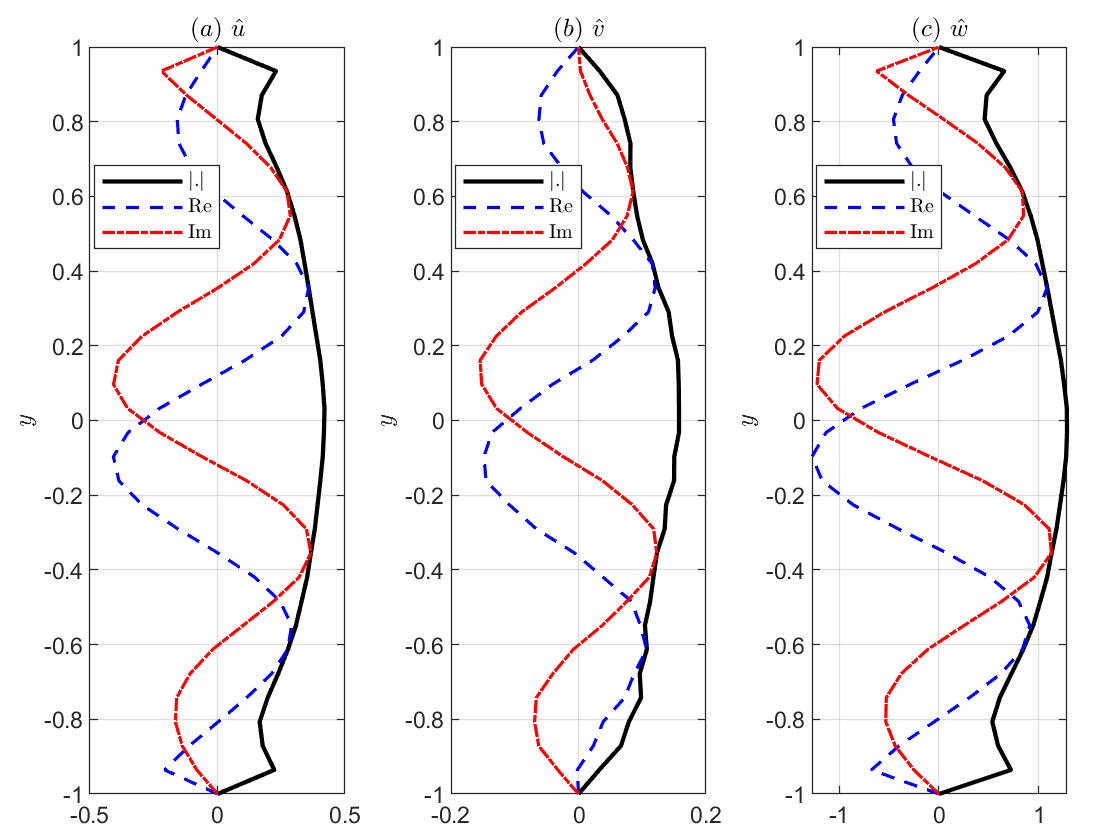




% vhat : Ny x 1 complex mode shape
% what : Ny x 1 complex mode shape
% scaleFactor : optional, e.g. 1e3 to mimic the paper style

% if ~exist('scaleFactor','var')
    scaleFactor = 1;
% end

uplot = scaleFactor * u_hat(:);
vplot = scaleFactor * v_hat(:);
wplot = scaleFactor * w_hat(:);
y = y_grid;

figure('Color','w','Name','Figure 6 style mode profiles');
tiledlayout(1,3,'Padding','compact','TileSpacing','compact');

% ---- uhat ----
nexttile;
plot(abs(uplot), y, 'k-', 'LineWidth', 1.6); hold on;
plot(real(uplot), y, 'b--', 'LineWidth', 1.2);
plot(imag(uplot), y, 'r-.', 'LineWidth', 1.2);
grid on;
% xlabel('value');
ylabel('$y$','Interpreter', 'latex');
title('($a$) $\hat{u}$','Interpreter', 'latex');
legend('$|.|$','Re','Im','Location','best','Interpreter', 'latex');
ylim([min(y), max(y)]);

% ---- vhat ----
nexttile;
plot(abs(vplot), y, 'k-', 'LineWidth', 1.6); hold on;
plot(real(vplot), y, 'b--', 'LineWidth', 1.2);
plot(imag(vplot), y, 'r-.', 'LineWidth', 1.2);
grid on;
% xlabel('value');
ylabel('$y$','Interpreter', 'latex');
title('($b$) $\hat{v}$','Interpreter', 'latex');
legend('$|.|$','Re','Im','Location','best','Interpreter', 'latex');
ylim([min(y), max(y)]);

% ---- what ----
nexttile;
plot(abs(wplot), y, 'k-', 'LineWidth', 1.6); hold on;
plot(real(wplot), y, 'b--', 'LineWidth', 1.2);
plot(imag(wplot), y, 'r-.', 'LineWidth', 1.2);
grid on;
% xlabel('value');
ylabel('$y$','Interpreter', 'latex');
title('($c$) $\hat{w}$','Interpreter', 'latex');
legend('$|.|$','Re','Im','Location','best','Interpreter', 'latex');
ylim([min(y), max(y)]);

function [x, D1, D2, D4,w] =finitediff(N,L)

%Differentiation matrix using finite difference scheme.
%This is suitable for Dirichlet boundary condition v(x=L/2)=v(x=-L/2)=0 at
%the boundary and Neumann boundary condition v'(x=L/2)=v'(x=-L/2)=0. 

dx=L/N;%get grid spacing. 

x=linspace(-L/2,L/2,N);%get the grid point location

x=x(2:end-1); %delete the first and last points that are zero. 

w=dx*ones(1,N-2);%integration weighting 

N_diff=N-2;%The size of differentiation matrices

%First order derivative based on central difference
%f'(x_i)=(f(x_{i+1})-f(x_{i-1})/(2*dx)
%We also use the boundary condition that x_0=x_N=0
D1_stencil=diag(-1*ones(1,N_diff-1),1)+diag(ones(1,N_diff-1),-1);
D1=D1_stencil/(2*dx);

%Second order derivative based on central difference
%f''(x_i)=(f(x_{i+1})-2f(x_i)+f(x_{i-1})/(dx^2)
%We also use the boundary condition that x_0=x_N=0
D2_stencil=(diag(-2*ones(1,N_diff))+diag(ones(1,N_diff-1),1)+diag(ones(1,N_diff-1),-1));
D2=D2_stencil/dx^2;

%Forth order derivative based on central difference
%f''''(x_i)=(f(x_{i+2})-4f(x_{i+1})+6f(x_i)-4f(x_{i-1})+f(x_{i-2})/(dx^4)
%This differentiation matrix only go through x_1 up to x_{N-1}
D4_stencil=(diag(6*ones(1,N_diff))+diag(-4*ones(1,N_diff-1),1)+diag(-4*ones(1,N_diff-1),-1)...
    + diag(ones(1,N_diff-2),2)+diag(ones(1,N_diff-2),-2));

%Here, we use the Neumann boundary condition that x_0'=x_N'=0
%such that x_1=x_{-1} and x_{N-1}=x_{N+1} for the ghost points. Then we
%also use the condition x_0 and x_N=0 to express all values based on x_1 up
%to x_{N-1}
D4_stencil(1,1)=D4_stencil(1,1)+1;
D4_stencil(end,end)=D4_stencil(end,end)+1;

D4=D4_stencil/dx^4;

end

function newmap = bluewhitered(m)
%BLUEWHITERED   Blue, white, and red color map.
%   BLUEWHITERED(M) returns an M-by-3 matrix containing a blue to white
%   to red colormap, with white corresponding to the CAXIS value closest
%   to zero.  This colormap is most useful for images and surface plots
%   with positive and negative values.  BLUEWHITERED, by itself, is the
%   same length as the current colormap.
%
%   Examples:
%   ------------------------------
%   figure
%   imagesc(peaks(250));
%   colormap(bluewhitered(256)), colorbar
%
%   figure
%   imagesc(peaks(250), [0 8])
%   colormap(bluewhitered), colorbar
%
%   figure
%   imagesc(peaks(250), [-6 0])
%   colormap(bluewhitered), colorbar
%
%   figure
%   surf(peaks)
%   colormap(bluewhitered)
%   axis tight
%
%   See also HSV, HOT, COOL, BONE, COPPER, PINK, FLAG, 
%   COLORMAP, RGBPLOT.


if nargin < 1
   m = size(get(gcf,'colormap'),1);
end


bottom = [0 0 0.5];
botmiddle = [0 0.5 1];
middle = [1 1 1];
topmiddle = [1 0 0];
top = [0.5 0 0];

% Find middle
lims = get(gca, 'CLim');

% Find ratio of negative to positive
if (lims(1) < 0) & (lims(2) > 0)
    % It has both negative and positive
    % Find ratio of negative to positive
    ratio = abs(lims(1)) / (abs(lims(1)) + lims(2));
    neglen = round(m*ratio);
    poslen = m - neglen;
    
    % Just negative
    new = [bottom; botmiddle; middle];
    len = length(new);
    oldsteps = linspace(0, 1, len);
    newsteps = linspace(0, 1, neglen);
    newmap1 = zeros(neglen, 3);
    
    for i=1:3
        % Interpolate over RGB spaces of colormap
        newmap1(:,i) = min(max(interp1(oldsteps, new(:,i), newsteps)', 0), 1);
    end
    
    % Just positive
    new = [middle; topmiddle; top];
    len = length(new);
    oldsteps = linspace(0, 1, len);
    newsteps = linspace(0, 1, poslen);
    newmap = zeros(poslen, 3);
    
    for i=1:3
        % Interpolate over RGB spaces of colormap
        newmap(:,i) = min(max(interp1(oldsteps, new(:,i), newsteps)', 0), 1);
    end
    
    % And put 'em together
    newmap = [newmap1; newmap];
    
elseif lims(1) >= 0
    % Just positive
    new = [middle; topmiddle; top];
    len = length(new);
    oldsteps = linspace(0, 1, len);
    newsteps = linspace(0, 1, m);
    newmap = zeros(m, 3);
    
    for i=1:3
        % Interpolate over RGB spaces of colormap
        newmap(:,i) = min(max(interp1(oldsteps, new(:,i), newsteps)', 0), 1);
    end
    
else
    % Just negative
    new = [bottom; botmiddle; middle];
    len = length(new);
    oldsteps = linspace(0, 1, len);
    newsteps = linspace(0, 1, m);
    newmap = zeros(m, 3);
    
    for i=1:3
        % Interpolate over RGB spaces of colormap
        newmap(:,i) = min(max(interp1(oldsteps, new(:,i), newsteps)', 0), 1);
    end
    
end
end
